# **Tutorial: Overview of how to use the MINT toolbox -  MI**

This tutorial provides an introduction to using the MI function from the MINT toolbox to compute Mutual Information. 

## Data simulation

We simulate spiking activity of two neurons to four stimuli values as a sum of two poisson processes (one independent and one shared) for each neuron with the following parameter (you can change them to see how they influence the PID atoms):

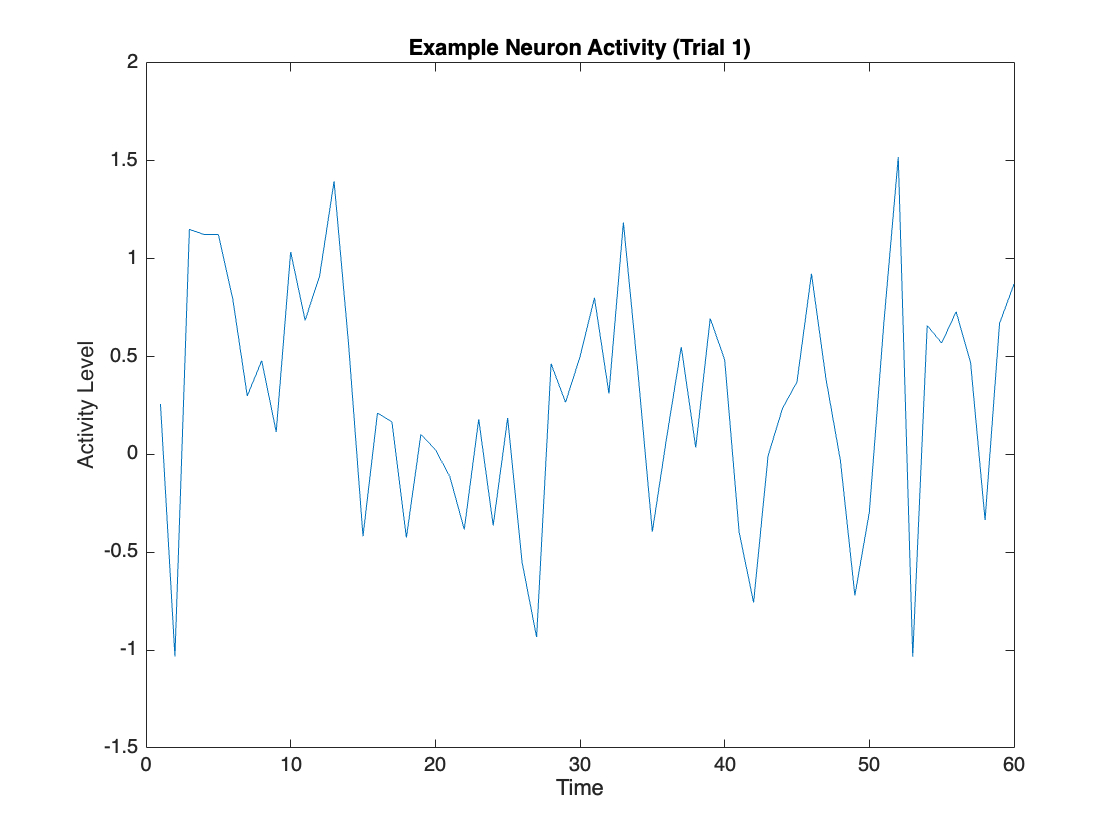

clc, clear
nNeurons = 10;          
nTimepoints = 60;        
nTrials = 200;  

baselineActivity = 0.2;  % Baseline activity level
noiseLevel = 0.6;        % Level of random noise in baseline activity
stimulus_amplitude = 4;  % Increase in activity for stimulus-responsive neurons


stimulus = randi([1, 2], 1, nTrials); % Randomly assign stimulus type 1 or 2 to each trial

% Assign neurons to respond to either stimulus 1, stimulus 2, or not respond
respond_to_stimulus1 = randperm(nNeurons, floor(nNeurons / 3)); 
remaining_neurons = setdiff(1:nNeurons, respond_to_stimulus1); 
respond_to_stimulus2 = remaining_neurons(randperm(length(remaining_neurons), floor(nNeurons / 3))); 
non_responsive_neurons = setdiff(1:nNeurons, [respond_to_stimulus1, respond_to_stimulus2]);

% Create baseline neural activity (nNeurons x nTimepoints x nTrials)
neural_data = baselineActivity + noiseLevel * randn(nNeurons, nTimepoints, nTrials);

% Embed stimulus-related activity for neurons responsive to stimulus 1
for neuron = respond_to_stimulus1
    response_window_start = randi([10, 40]); % Random start of window between time points 20 and 70
    response_window_length = randi([5, 20]); % Random length of window
    response_window_end = min(response_window_start + response_window_length, nTimepoints);    
    % Increase activity during the response window in each trial where stimulus == 1
    for trial = 1:nTrials
        if stimulus(trial) == 1
            neural_data(neuron, response_window_start:response_window_end, trial) = ...
                neural_data(neuron, response_window_start:response_window_end, trial) + stimulus_amplitude;
        end
    end
end

% Embed stimulus-related activity for neurons responsive to stimulus 2
for neuron = respond_to_stimulus2
    response_window_start = randi([20, 70]); % Random start of window between time points 20 and 70
    response_window_length = randi([5, 30]); % Random length of window
    response_window_end = min(response_window_start + response_window_length, nTimepoints);    
    % Increase activity during the response window in each trial where stimulus == 2
    for trial = 1:nTrials
        if stimulus(trial) == 2
            neural_data(neuron, response_window_start:response_window_end, trial) = ...
                neural_data(neuron, response_window_start:response_window_end, trial) + stimulus_amplitude;
        end
    end
end

% Visualize example data for a single neuron across time in a single trial
figure;
plot(squeeze(neural_data(1, :, 1)));
title('Example Neuron Activity (Trial 1)');
xlabel('Time');
ylabel('Activity Level');

### Settings of MI to compute the Mutual Information

#### 1. Compute the Mutual Information of each Neuron across time

The `MI` function is designed to compute mutual information (MI) and related information-theoretic measures between two sets of input data, referred to as A and B. These inputs are provided as a cell array, where `inputs{1}` corresponds to the first dataset (A) and `inputs{2}` corresponds to the second dataset (B). If either A, B, or both inputs are time series, the output will also be returned as a time series.

You can specify which types of entropy calculations you would like to perform by passing a cell array of strings in the `outputs` parameter. To compute the Mutual Information of A and B, specify {`'I(A;B)'} `as output request.

The `MI` function provides an array of optional parameters that can be specified using a structure. These options allow for customization of the mutual information calculations according to the user's requirements. If these parameters are not provided, the function will default to predefined settings.

The options you can define are: 

- 'bin_method'                 : specifies the method used to bin the data                                                   (default: none)                     

- 'n_bins'                         : specifies the number of bins                                                                        (default: 3)

- 'bias'                             : specifies the bias correction method                                                            (default: naive)

- ('xtrp'/'shuff')                 : further specification for the bias correction methods 'qe' and 'shuffSub'      (default: 10 xtrp/20 shuff)

- 'supressWarnings'        : option to supress warnings e.g. for missing opts fields                                (default: false)

- 'NaN_handling'             : specify how to deal with NaN values in the data                                          (default: error)

- 'computeNulldist'          : If set to true, generates a null distribution based on the specified inputs     (default: false)

% To bin your data, you must specify both the binning method and the number of bins. You can set different methods 
% or number of bins for each input. If only one is provided, it will be applied to all inputs. 
% For more details type 'help binning' in your Command Window.
MI_opts.bin_method = {'eqpop', 'none'};     % Options:                                      
                                            % 'eqpop' (equal population), 
                                            % 'eqspace' (equal spacing)
                                            % 'userEdges'
                                            % 'none' (no binning)                                   
MI_opts.n_bins = {3};                       % Specify an integer for the number of bins     


% To correct for sampling bias, you can specify methods for bias correction in the MINT toolbox. If its not naive 
% you will get the naive values as the second output of the functions. 
% For more details type 'help correction' in your Command Window.
MI_opts.bias = 'shuffSub';             % Options:                                           
                                            % 'naive' (no bias correction)                                                                       
                                            % 'qe' (Quadratic Extrapolation), 
                                            % 'le' (Linear Extrapolation), 
                                            % 'qe_shuffSub' (Quadratic with Shuffle Subtraction), 
                                            % 'le_shuffSub' (Linear with Shuffle Subtraction), 
                                            % 'shuffSub' (Shuffle Subtraction), 
                                            % 'pt' (Panzeri-Treves), 
                                            % 'bub' (BUB Correction), 
                                            % 'shuffCorr' (Shuffle Correction)

% If you use 'qe' you have to specify the number of extrapolations (opts.xtrp) the correction function should to. 
% If you use 'shuffSub' you have to specify the number of shufflings (opts.shuff) the correction function should to. 
MI_opts.shuff = 30;   

% Several functions give you warning, e.g. if you did not specify an opts field that is needed and the function is 
% using the default it will inform you. If you don't want to get these warning you can supress them with the opts field 
% supressWarnings (default: false).
MI_opts.supressWarnings = true;

MI_opts.NaN_handling = 'removeTrial';        % Options:                                          
                                             % 'error' (Throws an error if NaN values are detected in any input)
                                             % 'removeTrial' (Removes trials (across all variables) that contain NaN values)  

If we want to compute the Mutual Information for each neuron based on the above described options, we can call the function as follows: 

outputList = {'I(A;B)'};
for neuron = 1:nNeurons
    neuron_data = neural_data(neuron,:,:);
    inputs = {neuron_data, stimulus}   
    [MI_values, MI_naive, MI_nullDist] = MI(inputs, outputList, MI_opts)
end 




The MINT toolbox allows you to define optional parameters using a structure with various fields. For PID computation, you can specify the following options. If not provided, the function will use default options automatically.

The options you can define are: 

- 'redundancy_measure' : specifies the way the information quantity of each atom                             (default: I_BROJA)

- 'bin_method'                 : specifies the method used to bin the data                                                   (default: none)                     

- 'n_bins'                         : specifies the number of bins                                                                        (default: 3)

- 'bias'                             : specifies the bias correction method                                                            (default: naive)

- ('xtrp'/'shuff')                 : further specification for the bias correction methods 'qe' and 'shuffSub'      (default: 10 xtrp/20 shuff)

- 'pid_constrained'          : constrained PID or unconstrained                                                                (default: true)

- 'supressWarnings'        : option to supress warnings e.g. for missing opts fields                                (default: false)

- 'NaN_handling'             : specify how to deal with NaN values in the data                                          (default: error)

To get more information for the binning procedure or the bias correction type `help binning` or `help correction` in your Command Window

PID_opts.redundancy_measure = 'I_min';      % Options:                                                  
                                            % 'I_BROJA'
                                            % 'I_MMI'
                                            % 'I_min'                                              

% To bin your data, you must specify both the binning method and the 
% number of bins. You can set different methods or number of bins for each input; 
% If only one is provided, it will be applied to all inputs. 
% For more details type 'help binning' in your Command Window.
PID_opts.bin_method = {'eqpop', 'eqpop', 'none'};   % Options:                                         
                                                    % 'eqpop' (equal population), 
                                                    % 'eqspace' (equal spacing)
                                                    % 'threshold'
                                                    % 'none' (no binning)                                   
PID_opts.n_bins = {3, 3};                           % Specify an integer for the number of bins         


% For more details type 'help correction' in your Command Window.
PID_opts.bias = 'naive';                            % Options:                                        
                                                    % 'naive' (no bias correction)                                                                   
                                                    % 'qe' (Quadratic Extrapolation), 
                                                    % 'le' (Linear Extrapolation), 
                                                    % 'qe_shuffSub' (Quadratic with Shuffle Subtraction), 
                                                    % 'le_shuffSub' (Linear with Shuffle Subtraction), 
                                                    % 'shuffSub' (Shuffle Subtraction), 


% If you use 'qe' you have to specify the number of extrapolations (opts.xtrp) the correction function should to. 
% If you use 'shuffSub' you have to specify the number of shufflings (opts.shuff) the correction function should to. 
PID_opts.xtrp = 10;   

% In the case of two sources and one target MINT offers the option for shuffSub and qe, to compute the corrected PID atoms constrained to 
% the corrected information. This can be set with the option opts.pid_constrained:
PID_opts.pid_constrained = true;                    % Options.                                          
                                                    % true/false

PID_opts.supressWarnings = false;

PID_opts.NaN_handling = 'removeTrial';              % Options:                                          
                                                    % 'error' (Throws an error if NaN values are detected in any input)
                                                    % 'removeTrial' (Removes trials (across all variables) that contain NaN values)  

### Generating null distributions

To test for significance, you may want to generate a null distribution.The functions in the MINT toolbox offer an option to do this through the `opts.computeNulldist` parameter. To obtain the null distribution, set this option to `true` and specify the number of samples using `opts.n_samples` (default is 100). 

You can also indicate which variables should be shuffled to create the null distribution or specify if the shuffling should be conditioned on another variable using `opts.shuffling`. If you provide multiple shuffling definitions, the function will output one null distribution for each shuffling definition specified. (default: 'A' (just the firstinput variable is going to be shuffled). 

You can also specify the dimension that should be shuffled with opts.dim_shuffle. For 'Trials' it shuffles the last dimension, for 'Objects' the first and for 'Timepoints' the second.

For more information, type `help create_nullDist` in your Command Window.

PID_opts.computeNulldist = false;   % set to true to compute the null Distribution. If you want to make the script faster set to false  
PID_opts.parallel_sampling = true;   
PID_opts.n_samples = 20;
PID_opts.shuffling = {'AB', 'A'};
PID_opts.dim_shuffle = {'Trials'};

### PID Outputs

The function can output three variables based on the specified settings:

- **PID_values**: This is a cell array containing the PID values based on the specified outputs argument. Each cell represents one requested output in the same order as specified

- **PID_naive**: This cell array contains the naive estimates. These estimates are calculated without any bias correction. It is important to note that if no bias correction is performed during the computation, the PID_values will be identical to the PID_naive values.

- **PID_nullDist**: This output contains the results of the null distribution computation, which is useful for significance testing. If the null distribution is not computed, this output will be zero.

### Compute PID

Now we definied all possible options and we can compute the PID values with the following function call. As the inputs X1 and X2 are the spike trains over time, the output will give the PID atoms over time:

for neuron = 1:nNeurons
    neuron_data = neural_data(neuron,:,:);
    inputs = {neuron_data, stimulus}   
end 



inputs = {X1, X2, S};

### Plot Results